function exportTransparentSVG(filename)
    fig = gcf;
    set(fig, 'Color', 'none');
    ax = gca;
    set(ax, 'Color', 'none');
    set(fig, 'InvertHardcopy', 'off');  % Preserve transparency
    print(fig, filename, '-dsvg');
end

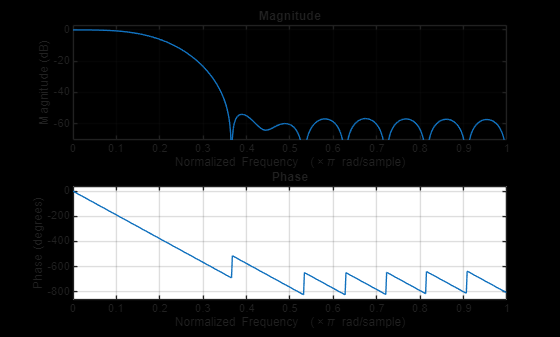

% 21st Order Low-Pass Filter
Order = 21; 
Wn = 0.2; 
b = fir1(Order, Wn, 'low');
freqz(b,1,512)

exportTransparentSVG('low.svg')

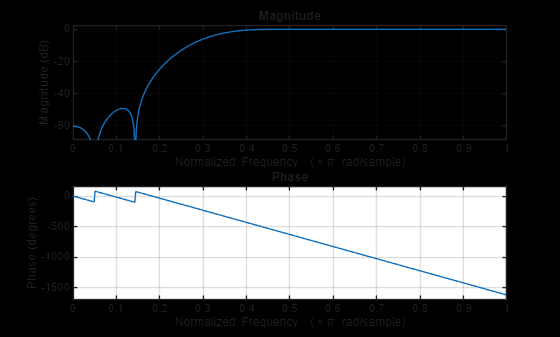

% 22st Order High-Pass Filter
Order = 22; 
Wn = 0.3; 
b = fir1(Order, Wn, 'high');
freqz(b,1,512)

exportTransparentSVG('high.svg')

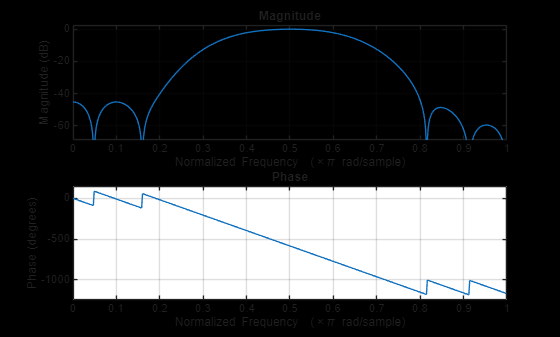

% 21st Order band-Pass Filter
Order = 21; 
Wn = [0.35 0.65]; 
b = fir1(Order, Wn);
freqz(b,1,512)

exportTransparentSVG('band.svg')